**Linear Support Vector Machine with slack variables - Dual problem**

Solve the dual problem of the linear SVM with slack variables (set ε = 0.2 and C = 10) applied to the training data. Moreover, find the support vectors.

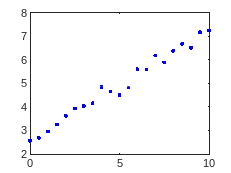

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

data = [ 0    2.5584
    0.5000    2.6882
    1.0000    2.9627
    1.5000    3.2608
    2.0000    3.6235
    2.5000    3.9376
    3.0000    4.0383
    3.5000    4.1570
    4.0000    4.8498
    4.5000    4.6561
    5.0000    4.5119
    5.5000    4.8346
    6.0000    5.6039
    6.5000    5.5890
    7.0000    6.1914
    7.5000    5.8966
    8.0000    6.3866
    8.5000    6.6909
    9.0000    6.5224
    9.5000    7.1803
   10.0000    7.2537];

x = data(:,1);
y = data(:,2);
l = length(x);

% Plot the dataset
plot(x,y,'b.');

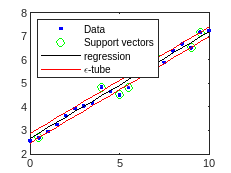

% Environment variables
epsilon = 0.2;
C = 10;

% Define the problem
X = zeros(l,l);
for i = 1 : l
    for j = 1 : l
        X(i,j) = x(i)*x(j);
    end
end
Q = [ X -X ; -X X ]; 
c = epsilon*ones(2*l,1) + [-y;y]; 

% solve the problem
options = optimset('Display', 'off');
solution = quadprog(Q,c,[],[],[ones(1,l) -ones(1,l)],0,zeros(2*l,1),C*ones(2*l,1), [], options);
lap = solution(1:l);
lam = solution(l+1:2*l);

% compute w
w = (lap-lam)'*x ;

% compute b
ind = find(lap > 1e-3 & lap < C-1e-3);
if ~isempty(ind)
    i = ind(1);
    b = y(i) - w*x(i) - epsilon ;
else
    ind = find(lam > 1e-3 & lam < C-1e-3);
    i = ind(1);
    b = y(i) - w*x(i) + epsilon ;
end

% find regression and epsilon-tube
z = w.*x + b ;
zp = w.*x + b + epsilon ;
zm = w.*x + b - epsilon ;

%% plot the solution

% find support vectors
sv = [find(lap > 1e-3);find(lam > 1e-3)]; 
sv = sort(sv);

plot(x,y,'b.',x(sv),y(sv),...
    'go',x,z,'k-',x,zp,'r-',x,zm,'r-');

legend('Data','Support vectors',...
    'regression','\epsilon-tube',...
    'Location','NorthWest')